%{
    ES115 Streetlight brightness model problem
 originally from Module 1 project bank.pdf - 02/02/2026 
Author: Gracy Sylvestre
Version: 1.0
Date: 2026-04-24
State the problem (Purpose): Brightness models are created to display two
different streelight along with their position and brightness level. 

Describe input values (Knowns)and required output (Unknowns) 
    Input:
        - vertex form of brightness model
       - evaluation range
      - user input : k, h, Bmax, x
    Output:
        - brightness curves
       - maximum brightness and location
      - intersection points
     
  Engineering Workflow and Algarithems:
    - Setup equations
    - define domain
    - assign parameters 
    - plot both curves
    - find intersection
    - present results

MATLAB tools/functions:
    - MATLAB plotting
    - user input
    - fprintf
    - logic, loops , functions
    - script structure

%}


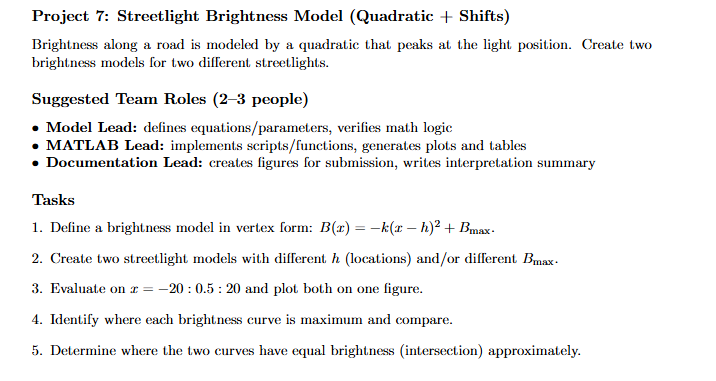

## Task 1: Define a brightness model in vertex form: B(x) = −k(x − h)2 + Bmax.

%B(x) = -k*(x-h)^2 + Bmax   % Bmax: maximum brightness under streetlight

## Task 2: Create two streetlight models with different h (locations) and/or different Bmax.

% Allow user to define streetlight parameters

fprintf("Enter parameters for Streetlight 1:\n");

Enter parameters for Streetlight 1:


k1 = input("Enter spread factor k1 (e.g., 0.3): ");
h1 = input("Enter position h1 (e.g., -1): ");
Bmax1 = input("Enter max brightness Bmax1: ");

fprintf("\nEnter parameters for Streetlight 2:\n");


Enter parameters for Streetlight 2:


k2 = input("Enter spread factor k2 (e.g., 0.4): ");
h2 = input("Enter position h2 (e.g., 5): ");
Bmax2 = input("Enter max brightness Bmax2: ");


% Default values if user enters nothing (C7: logic) 
%streetlight 1 values
if isempty(k1); k1 = 0.7; end % streetlight 1 fall off
if isempty(h1); h1 = 4; end   % light 1 location on x axis
if isempty(Bmax1); Bmax1 = 80; end % streetlight 1 max brightness

%streetlight 2 values
if isempty(k2); k2 = 0.9; end % streetlight 2 fall off
if isempty(h2); h2 = 6; end % light 2 location on x axis
if isempty(Bmax2); Bmax2 = 100; end % streetlight 2 max brightness


### Task 3: Evaluate on x = −20 : 0.5 : 20 and plot both on one figure.

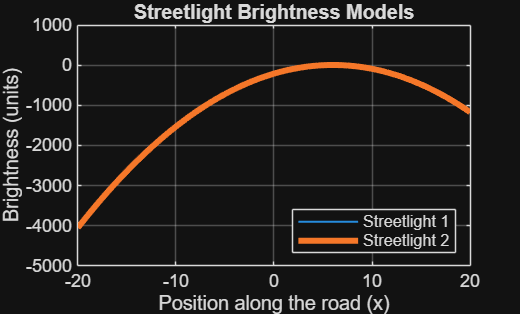

x = -20 : 0.5: 20;  % define section in which the brightness will be evaluated

B1 = -k1 * (x - h1).^2 + Bmax1;  % Brightness model for streetlight 1
B2 = -k2 * (x - h2).^2 + Bmax2;  % Brightness model for streetlight 2

%create graph and plot both streetlight models
figure;
plot(x, B1, 'LineWidth', 1); hold on; % plot streetlight 1 on graph, no specified color or shape

plot(x, B2, 'LineWidth', 3); %plot streetlight 1 on graph, no specified color or shape

xlabel('Position along the road (x)'); % define x axis label

ylabel('Brightness (units)'); %define y axis label

title('Streetlight Brightness Models'); %title the graph created

legend('Streetlight 1', 'Streetlight 2', 'Location',' southeast'); % define variables and locate the legend (bottom right corner)
grid on;

## Task 4: Identify where each brightness curve is maximum and compare

% maximum: vertex of each porabola at x=h

maxloc1 = h1;  % location of max brightness for light 1 (curve 1 vertex)
maxBright1 = Bmax1; %locate the max

maxloc2 = h2;  % location of max brightness for light 2 (curve 2 vertex)
maxBright2 = Bmax2; %locate the max

%display location of max brightness on both lights along with their values
fprintf('Streetlight 1 maximum at x = %.2f with brightness %.2f\n', maxloc1, maxBright1); 

Streetlight 1 maximum at x = 6.00 with brightness 6.00


fprintf('Streetlight 2 maximum at x = %.2f with brightness %.2f\n', maxloc2, maxBright2);

Streetlight 2 maximum at x = 6.00 with brightness 6.00


## Task 5: Determine where the two curves have equal brightness (intersection) approximately

% Compute difference between curves
diff = B1 - B2;

% Find where sign changes (approximate intersection)
int_index = [];

for a = 1:length(diff)-1
    if diff(a) * diff(a+1) < 0   % Sign change 
        int_index(end+1) = a;
    end
end


% Display intersection found
fprintf("\nApproximate Intersection Points:\n");


Approximate Intersection Points:



for a = 1:length(int_index)
    int = int_index(a);
    fprintf("x ≈ %.2f\n", x(int));
    
    % Plot intersection point on created graph
    plot(x(int), B1(int), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); 
end



%{ 
IN PROGRESSSSSSS

Reflection After Completing the Project:

- What did you learn?
 Throughout my completion of this project, I was able to work on and
    add to the many tools and techniques that matlab has to offer. Going
    into this course matlab was an unfamilar resource to me and despite all
    of the research that had went into the weeks prior for preperatio of
    thius project, I still felt somewhat unprepared. Despite that, this
    project has allowed me to test different functions that I haven't been
    able to throuroughly utilize in the past such as, fprintf, table
    functions, intersection values on a graph, etc. 
 
  - What could be done differently?
many features among this project couldv'e been done differently such as including a user input system, testing more functions, etc. 
   
- Rate the project (1 - 10) (1 - represents simple and 10 represents difficult) 
   Rate : 6 
The most difficult thing about these projects is knowing where to begin,
especially when you are extremely unfamilar with the technology at hand.
However, the use of if/else statements allowed me to power through what I
felt was the most difficult section of this project.
%}
